load logmap.mat
format long g

order_list=1:1:60;
run = [1:50];

simplex =[];
mse_loop = [];

Ztrain=Z(1:100,:);
Ztrain_p=Z(101:150,:);

i=1; 
for order=order_list,
    
    
    X = windowize (Ztrain , 1:(order + 1));
    Y = X (: , end );
    X = X (: , 1: order);

    for r=run,
        disp(['Run Simplex', num2str(r)])
        [gam, sig2 , cost] = tunelssvm ({ X , Y , 'function estimation', [], [], 'RBF_kernel'}, 'simplex', 'crossvalidatelssvm',{10, 'mse'});
        simplex=[simplex; order, gam, sig2, cost];
    end 

    gam = median(simplex(i, 2)); 
    sig2 = median(simplex(i, 3)); 

    Xs = Ztrain(end - order +1: end , 1);

    nb = length(Ztrain_p);
    prediction = predict ({X , Y , 'f', gam, sig2 } , Xs , nb ) ;
    mse = sum((prediction-Ztrain_p).^2)/nb;
    
    mse_loop = [mse_loop; order, mse, gam, sig2];

    disp(['SIMPLEX -- Lag: ', num2str(order),'   ', 'MSE: ' , num2str(mse_loop(i,2)), '  '])
    
    i=i+1;
end


[M,I] = min(mse_loop(:,2))

M =         0.0496875745967186


I =     59


mse_loop(55,:)

ans =                         55        0.0496918097629274          458.461192906277          30.5658308372075


mse_loop

order= mse_loop(55,1)

order =     55


gam= mse_loop(55,3)

gam =           458.461192906277


sig2= mse_loop(55,4)

sig2 =           30.5658308372075



X = windowize (Ztrain, 1:( order + 1) ) ;
Y = X (: , end ) ;
X = X (: , 1: order ) ;
Xs = Z(end - order +1: end , 1) ;

nb = length(Ztest);
prediction = predict ({ X , Y , 'f', gam , sig2} , Xs , nb ) ;
mse = sum((prediction-Ztest).^2)/nb

mse =         0.0564261531811928


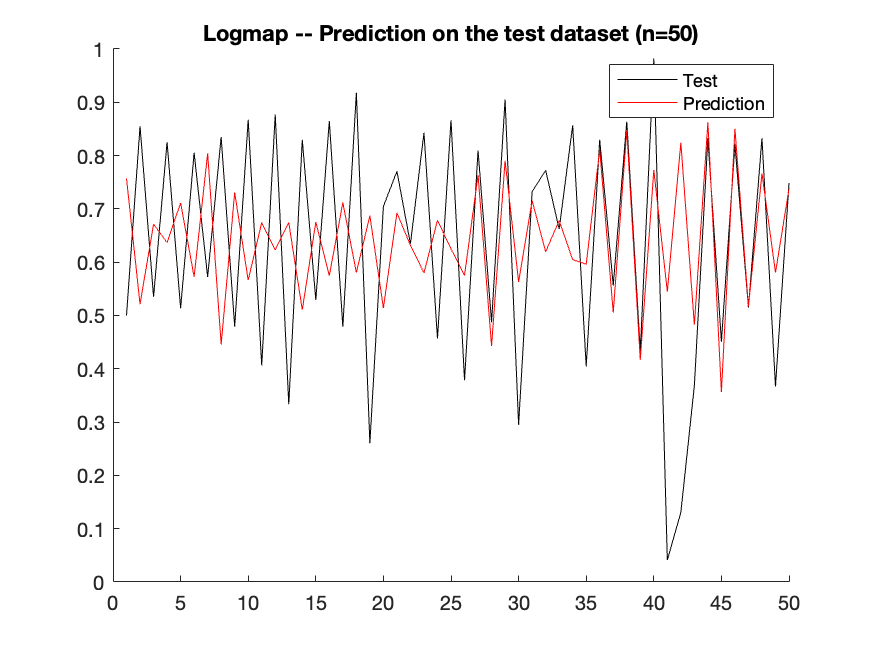

figure ;
hold on;
plot ( Ztest , 'k') ; 
plot ( prediction , 'r') ;
legend( 'Test','Prediction')
title('Logmap -- Prediction on the test dataset (n=50)')
hold off;


f = gcf;
exportgraphics(f,'/Users/serg/github_projects/QASS_SVM/manuscript/figures2/fig2_24_1.png','Resolution',300)